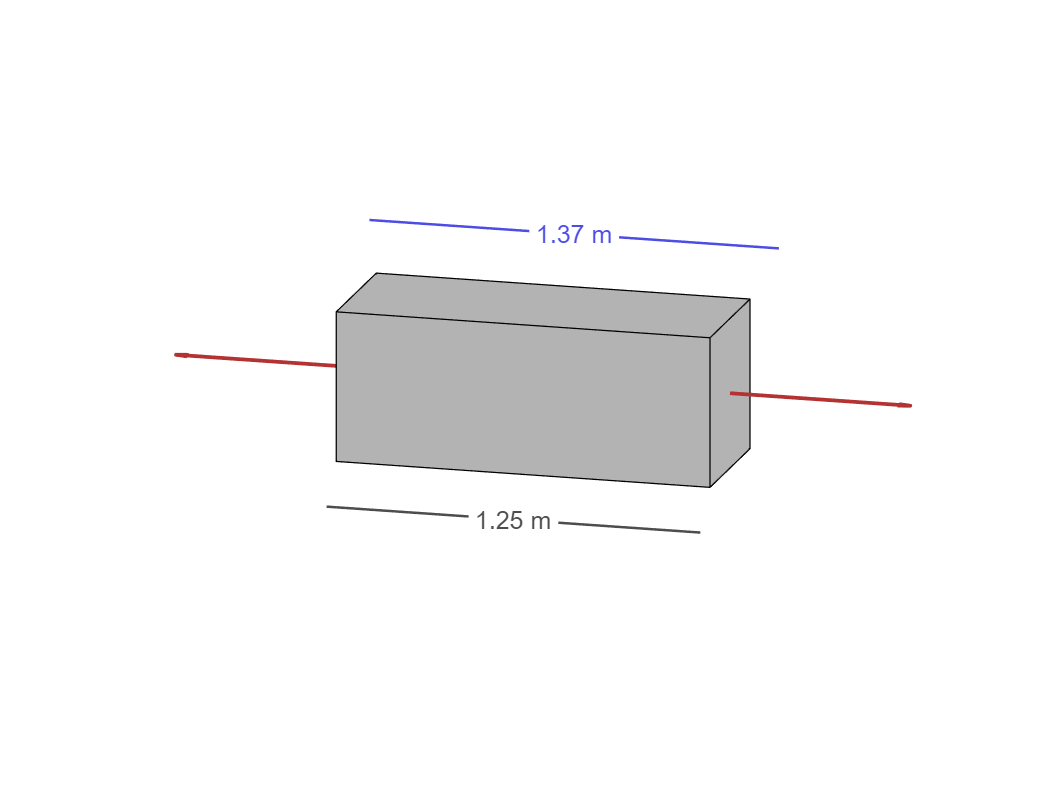

close all

nu = 0.5; % Poisson's ratio
F =670* 1e6; % Axial force (N)
E = 28* 1e9; % Young's modulus (Pa)
L0 = 1.25;   % Initial length (m)
w0 = 0.5;   % Initial width (m)

visualizeAxialStressStrain(F, E, L0, nu, w0);
view([105 15])

function visualizeAxialStressStrain(F, E, L0, nu, w0)
    
    % Calculations
    % 6666666666 check these calculations
    sigmaL = F/(w0*w0); % In N/m^2 = Pa
    epsL = sigmaL/E; % In     
    L = epsL*L0 + L0;
    deltaL = epsL*L0;
    longStretch = L/L0;
    epsT = - nu*epsL; % Transverse strain
    transverseStretch = epsT + 1 - 1e-3;

    % end 666
    
    % Visualization parameters
    cubeEdgeAlpha = 1;
    cubeAlpha = 1;
    cubeAlphaDeformed = 0.5;
    cubeColors = [1 1 1]*0.7;
    cubeColorsDeformed = [50 50 180]/255;
    forceColor = [180 50 50]/255;
    axLims = [-1 1 -2 2 -1 1]*0.6;
    Fscale = 1e-9;
    Flw = 1.5;
    
    % Cube and deformations
    [vertices,faces,normals] = cubeValues();
    vertices = vertices - 0.5;
    vertices(:,2) = vertices(:,2)*L0;
    vertices(:,[1,3]) = vertices(:,[1,3])*w0;
    verticesDeformed = vertices;
    verticesDeformed(:,2) = verticesDeformed(:,2)*longStretch;
    verticesDeformed(:,[1,3]) = verticesDeformed(:,[1,3])*transverseStretch;
    
    % Create plot
    patch("Vertices",vertices,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
        "FaceColor","Flat","FaceVertexCData",cubeColors,"FaceAlpha",cubeAlpha);
    hold on
%     patch("Vertices",verticesDeformed,"Faces",faces,"EdgeAlpha",cubeEdgeAlpha,...
%         "FaceColor","Flat","FaceVertexCData",cubeColorsDeformed,"FaceAlpha",cubeAlphaDeformed);

    % Force vectors
    ymneg = mean(vertices([1 2 5 6],2));
    quiver3(0,ymneg,0,0,-F*Fscale,0,"Color",forceColor,"LineWidth",Flw)
    ympos = mean(vertices([3 4 7 8],2));
    quiver3(0,ympos,0,0,F*Fscale,0,"Color",forceColor,"LineWidth",Flw)

    % Label for L0
    xyz1 = vertices(2,:)';
    xyz2 = vertices(3,:)';
    offsetVector = [1; 0; -1]*0.12;
    labelText = num2str(L0,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.3]);

    % Label for L
    xyz1 = verticesDeformed(5,:)';
    xyz2 = verticesDeformed(8,:)';
    offsetVector = -[1; 0; -1]*0.15;
    labelText = num2str(L,3) + " m";
    dimensionLabel(xyz1,xyz2,offsetVector,labelText,[0.3,0.3,0.9]);

    hold off
    view(120,20)
    axis equal
    axis(axLims)
    set(gca,"Clipping","off")
    axis off
end

function [vertices,faces,normals] = cubeValues()
    vertices = [0 0 0; 1 0 0; 1 1 0; 0 1 0;
                0 0 1; 1 0 1; 1 1 1; 0 1 1];
    faces = [1 2 3 4 1; 5 6 7 8 5; 1 2 6 5 1; 
             3 4 8 7 3; 1 4 8 5 1; 2 3 7 6 2];
    normals = [0 0 -1; 0 0 1; 0 -1 0; 0 1 0; -1 0 0; 1 0 0];
end

function dimensionLabel(xyz1,xyz2,offsetVector,labelText,color)
    mag = norm(xyz1-xyz2);
    xyzm = (xyz1 + xyz2)/2;
    xyzm1 = (xyz1*(0.5+0.15/mag) + xyz2*(0.5-0.15/mag));
    xyzm2 = (xyz1*(0.5-0.15/mag) + xyz2*(0.5+0.15/mag));
    plot3([xyz1(1),xyzm1(1),NaN,xyzm2(1),xyz2(1)]+offsetVector(1),...
          [xyz1(2),xyzm1(2),NaN,xyzm2(2),xyz2(2)]+offsetVector(2),...
          [xyz1(3),xyzm1(3),NaN,xyzm2(3),xyz2(3)]+offsetVector(3),...
          "-","Color",color,"LineWidth",1)

    xyzt = xyzm + offsetVector;

    text(xyzt(1),xyzt(2),xyzt(3),labelText,"Color",color,...
        "VerticalAlignment","middle","HorizontalAlignment","center");

end